**Submitted By**

**Hridya Divakaran : V00970167**

**Sanjana Arora : V00966221 **

**Q1 Load the Exercise 7 Data Set, which consists of drawn data from two classes. For the first measurement feature vector apply an appropriate statistical goodness-of-fit test to determine whether or not the this feature is Gaussian.**

clear;
clc;
%rng(1)
% Load the Exercise 7 data set.
load ('Exercise_7_Data.mat');

## Goodness of fit test

class_0 = find(class == 0);
class_1 = find(class == 1);

data_class_0 = data(class_0,:);
data_class_1 = data(class_1,:);

feature_data_class_0 = data_class_0(:,1);
feature_data_class_1 = data_class_1(:,1);


feature_data_class_0_test = chi2gof(feature_data_class_0)

feature_data_class_0_test = 1

feature_data_class_1_test = chi2gof(feature_data_class_1)

feature_data_class_1_test = 0

As indicated above, the chi square test on feature 1 data belonging to class 0 yields a value of 1 suggesting that class 0 data of feature 1 has failed the chi square test. H =1, suggests that the class 0 data of feature 1 is non-gaussian in nature.

The class 1 feature 1 data has passed the chi square test which suggests that the class 1 data of feature 1 is gaussian data.

Overall, the feature 1 data is non-gaussian.

**Q2 Determine the Bayes classification error rate for the data if the analysis is based *****solely *****on data taken from the first measurement feature. Note you can no longer simply assume that the data for each class is Gaussian distributed. Moreover, Bayes classification does *****not *****make this assumption but, instead applied generally to *****any *****class distribution.**

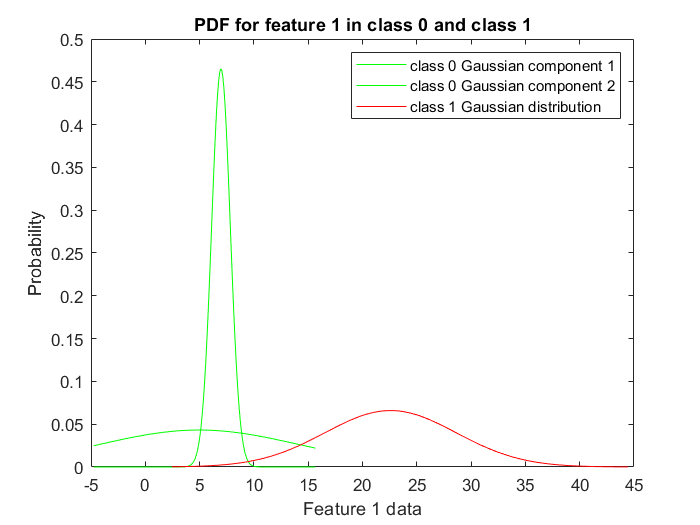

X = feature_data_class_0;

% Gaussian mixture model feature 1 in class 0

AIC = zeros(1,4);
gm = cell(1,4);
options = statset('MaxIter', 500);

for k = 1:4
    gm{k} = fitgmdist(X,k,'Options', options, 'CovarianceType', 'diagonal');
    AIC(k)= gm{k}.AIC;
end

[minAIC,numComponents] = min(AIC);
bestmodel = gm{numComponents};

p = bestmodel.ComponentProportion;
mu = bestmodel.mu;
sigma = bestmodel.Sigma;
gm = gmdistribution(mu, sigma, p');

mean_class_0 = mu(1);
std_class_0 = sigma(1);

mu_feature_data_class_1 = mean(feature_data_class_1);
std_feature_data_class_1 = std(feature_data_class_1);



min_class_0 = min(feature_data_class_0);
min_class_1 = min(feature_data_class_1);

max_class_0 = max(feature_data_class_0);
max_class_1 = max(feature_data_class_1);


x_1 = min_class_0 : 0.1 : max_class_0;
x_2 = min_class_1 : 0.1 : max_class_1;
y_2 = normpdf(x_2, mu_feature_data_class_1, std_feature_data_class_1);

% plotting the data for the two classes
plot_data(x_1,mu,sigma)
plot(x_2, y_2, 'red');
legend('class 0 Gaussian component 1', 'class 0 Gaussian component 2', 'class 1 Gaussian distribution');
hold off;

intersection_area = common_area (mean_class_0, mu_feature_data_class_1, std_class_0, std_feature_data_class_1);

% as class 1 is contributing most to the classification error, we calculate
% the boundary within the smallest deviation to class 1
std_dev_check = (mu_feature_data_class_1 - intersection_area) / std_feature_data_class_1;
min_index = find(min(abs(std_dev_check)) == abs(std_dev_check));
intersection_feature_2_final = intersection_area(min_index);

% The two class PDFs
fx_0 = @(x) 1 / (std_class_0 * sqrt(2 * pi)) * exp(-0.5 * power(((x - mean_class_0) / std_class_0), 2));
fx_1 = @(x) 1 /(std_feature_data_class_1 * sqrt(2 * pi))  * exp(-0.5 * power(((x - mu_feature_data_class_1) / std_class_0), 2));

% calculating prior probabilities of classes
prior_prob_0 = length(class_0) / length(class);
prior_prob_1 = length(class_1) / length(class);

%Type 1 and type 2 error
result_feature1_class_0 = integral(fx_0, intersection_feature_2_final, inf);
result_feature1_class_1 = integral(fx_1, -inf, intersection_feature_2_final);
error_rate_feature_1 = prior_prob_0 * result_feature1_class_0 + prior_prob_1 * result_feature1_class_1

error_rate_feature_1 = 8.4265e-04

From Q1, we observed that the class 0 data of feature 1 is non-gaussian and hence, gaussian mixture model has been used to find the best values of covariance and mean to generate the PDF of feature 1 data of class 0. 

Since, class 1 data of Feature 1 is gaussian in nature, we have used the MATLAB mean and std functions to find the mean and standard deviation statistics to plot the class 1 data PDF.

After plotting the PDFs of the feature data of two classes, we find the decision boundary between the two PDFs followed by finding the type 1 and type 2 error. The sum of type 1 and type 2 errors correspond to the bayes error.

**Q3 Determine the Bayes classification error rate for the data if the analysis is based *****solely *****on data taken from the *****second *****measurement feature.**

data_class_0 = data(class_0,:);
data_class_1 = data(class_1,:);

feature2_data_class_0 = data_class_0(:,2);
feature2_data_class_1 = data_class_1(:,2);

feature2_data_class_0_test = chi2gof(feature2_data_class_0)

feature2_data_class_0_test = 0

feature2_data_class_1_test = chi2gof(feature2_data_class_1)

feature2_data_class_1_test = 0

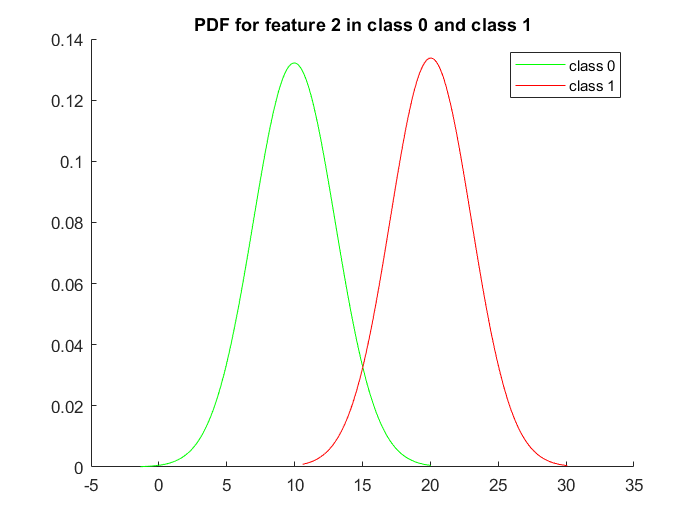

mean_feature2_data_class_0 = mean(feature2_data_class_0);
mean_feature2_data_class_1 = mean(feature2_data_class_1);
std_feature2_data_class_0 = std(feature2_data_class_0);
std_feature2_data_class_1 = std(feature2_data_class_1);

feature2_min_class_0 = min(feature2_data_class_0);
feature2_min_class_1 = min(feature2_data_class_1);

feature2_max_class_0 = max(feature2_data_class_0);
feature2_max_class_1 = max(feature2_data_class_1);

% plotting the data for the two classes
x_1 = feature2_min_class_0 : 0.1 : feature2_max_class_0;
y_1 = normpdf(x_1, mean_feature2_data_class_0, std_feature2_data_class_0);
x_2 = feature2_min_class_1 : 0.1 : feature2_max_class_1;
y_2 = normpdf(x_2, mean_feature2_data_class_1, std_feature2_data_class_1);

figure();
hold on;
plot(x_1, y_1, 'green');
plot(x_2, y_2, 'red');
title('PDF for feature 2 in class 0 and class 1');
legend('class 0', 'class 1');
hold off;


intersection_area = common_area(mean_feature2_data_class_0, mean_feature2_data_class_1, std_feature2_data_class_0, std_feature2_data_class_1);

% The intersection of two PDFs is the boundary of two classes
% Aim to find out the intersection/boundary within the smallest standard deviation to class 1
% as it contributes the most to the Bayes classification error rate.
std_dev_check = (mean_feature2_data_class_1 - intersection_area) / std_feature2_data_class_1;
min_index = find(min(abs(std_dev_check)) == abs(std_dev_check));
intersection_feature_2_final = intersection_area(min_index);

% The two class PDFs
fx_0 =  @(x) 1 / (std_feature2_data_class_0 * sqrt(2 * pi)) * exp(-0.5 * power(((x - mean_feature2_data_class_0) / std_feature2_data_class_0), 2));
fx_1 =  @(x) 1 /(std_feature2_data_class_1 * sqrt(2 * pi))  * exp(-0.5 * power(((x - mean_feature2_data_class_1) / std_feature2_data_class_0), 2));

%Type 1 and type 2 error
result_feature2_class_0 = integral(fx_0, intersection_feature_2_final, inf);
result_feature2_class_1 = integral(fx_1, -inf, intersection_feature_2_final);
error_rate_feature_2 = prior_prob_0 * result_feature2_class_0 + prior_prob_1 * result_feature2_class_1

error_rate_feature_2 = 0.0482

## Cross checking the error derived using the analytical form with the bayes classifier error rate

gk_A = discriminant_fn(mean_feature2_data_class_1, std_feature2_data_class_1, prior_prob_0,data(:,2));
gk_B = discriminant_fn(mean_feature2_data_class_0, std_feature2_data_class_0, prior_prob_1,data(:,2));
region_A_Bayes = find(gk_A > gk_B);
region_B_Bayes = find(gk_B > gk_A);

% creating a matrix and storing the bayesian classification results into the matrix
result_1 = zeros(1,length(data(:,2)));
result_1(region_A_Bayes) = 1;
result_1(region_B_Bayes) = 0;
result_label_Bayes = result_1;


bayes_classifier_error = sum(result_label_Bayes ~= class) / length(data(:,2))

bayes_classifier_error = 0.0473

We performed the chi square test on class 0 and class 1 data of feature 2 and observe that the data of both the classes of feature 2 follow gaussian distribution. Therefore, we have used MATLAB mean and std functions to find the mean and standard deviation statistics of the feature 2 data belonging to class 0 and class 1.

We find the bayes error using the analytical method of finding the sum of Type 1 and type 2 errors. Since, the feature 2 data is gaussian in nature, we also use the bayes classifier to find the bayes error. By using the error derived from the bayes classifier we cross check the errors derived from the analytical method and bayes classifier. As observed above, the error derived from bayes classifier 0.0473 is approx. similar to the one derived analytically 0.0482.

function intersection = common_area(mean_0, mean_1, std_0, std_1)

    syms x
    eqn = power(((x - mean_0) / std_0), 2) - power(((x - mean_1) / std_1), 2) + (2 * log(std_0 / std_1)) == 0;
    result_feature_1 = solve(eqn, x);
    intersection = double(vpa(result_feature_1));

end



function plot_data(x,mu,sigma)

figure();
for i = 1:length(mu)
    y = normpdf(x, mu(i), sigma(i));
    plot(x, y, 'green');
    hold on;
end

title('PDF for feature 1 in class 0 and class 1');
xlabel('Feature 1 data');
ylabel('Probability');

end


function g_x = discriminant_fn(mu,sigma,prior_prob,x)
w1 = (-1/2)*inv(sigma);

w2 = inv(sigma)*mu;

w3 = (-1/2)*mu'*inv(sigma)*mu - (1/2)*log(det(sigma)) + log(prior_prob);

g_x = sum((x*w1.').*x,2).' + w2'*x' + w3;


end